# Example 2.3: Pdf and Cdf of Discrete Bernoulli RV

Note: this script reproduces Example 2.3 (Section 2.1.2) of **Statistics for Chemical Engineers**: the Bernoulli RV B(0.3). Victor Z UW-Madison, 2019 pdf and cdf of a Bernoulli RV

clc; clear all; close all hidden;

## Pdf

pdf

p=0.3;
x=[-1 0 1 2];
f=[0 (1-p) p 0];
n=length(x);

## Cdf

compute cdf

t = linspace(-1,2);
for i=1:length(t)
    F(i)=0;
    for j=1:length(x)
    F(i)=F(i)+(x(j)<=t(i))*f(j);
    end
end


figure(1)

## Realizations

generate samples

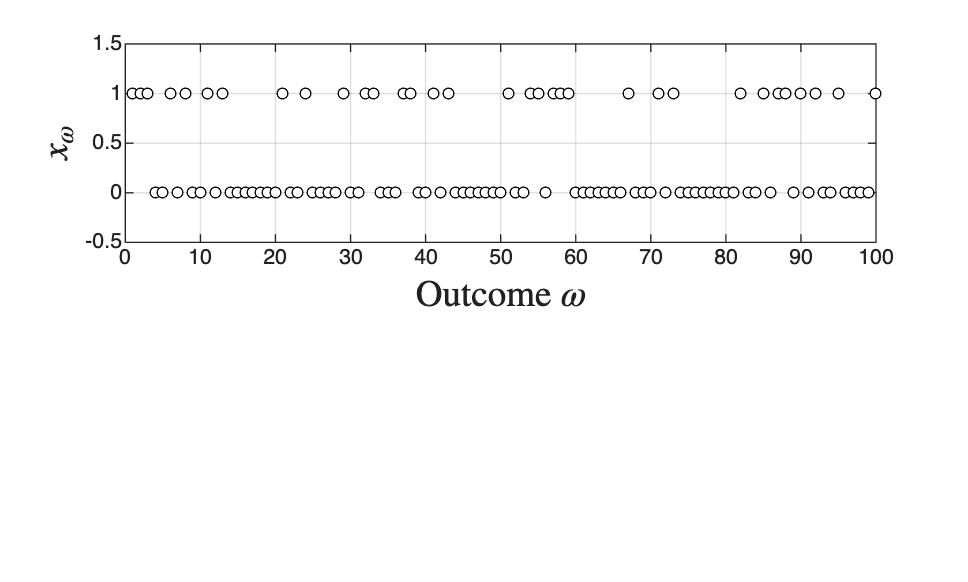

S=100;
X=binornd(1,p,S,1);
figure(1)
subplot(2,2,[1 2])
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
yticks([-0.5 0 0.5 1 1.5])
axis([0 S -0.5 1.5])

## Plots

visualize pdf

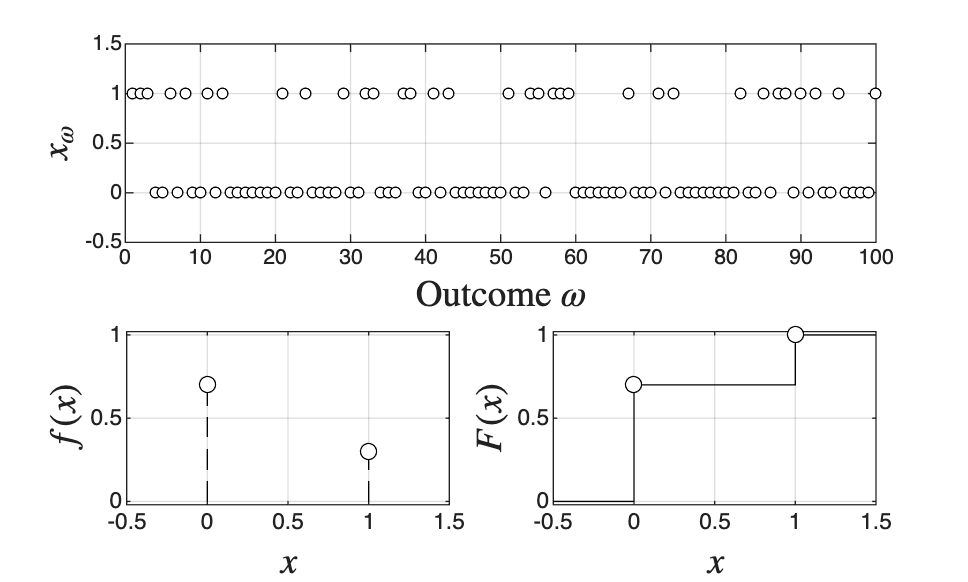

subplot(2,2,3)
plot(0*ones(100,1),linspace(0,f(2),100),'black--')
hold on
plot(1*ones(100,1),linspace(0,f(3),100),'black--')
hold on
scatter(x,f,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
axis([-0.5 1.5 -0.02 1.02])

%visualize cdf
subplot(2,2,4)
stairs(t,F,'black-')
hold on
for j=1:n
    scatter(x(j),interp1(t,F,x(j),'nearest'),'MarkerFaceColor','w','MarkerEdgeColor','black')
    hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
axis([-0.5 1.5 -0.02 1.02])

print -depsc ch2_pdfcdfbernoulli.eps

## Note

The domain is {0, 1}, with f(1) = 0.3 and f(0) = 0.7; note how the observations land unevenly across the two values.